# **Chapter 4:  Classification**

## **4.6 Lab: Logistic Regression, LDA, QDA, and KNN**

### **4.6.1 The Stock Market Data**

Load file Smarket.csv 

clear all; clc; close all;
Smarket = readtable("Data\Smarket.csv", 'TreatAsEmpty',{'?','NA','N/A'},'ReadRowNames', true);
Smarket.Direction = categorical(Smarket.Direction);
size(Smarket)

ans =         1250           9


Smarket.Properties.VariableNames

ans = 1×9 cell array
    {'Year'}    {'Lag1'}    {'Lag2'}    {'Lag3'}    {'Lag4'}    {'Lag5'}    {'Volume'}    {'Today'}    {'Direction'}


summary(Smarket);


Variables:

    Year: 1250×1 double

        Values:

            Min        2001 
            Median     2003 
            Max        2005 

    Lag1: 1250×1 double

        Values:

            Min       -4.922
            Median     0.039
            Max        5.733

    Lag2: 1250×1 double

        Values:

            Min       -4.922
            Median     0.039
            Max        5.733

    Lag3: 1250×1 double

        Values:

            Min       -4.922
            Median    0.0385
            Max        5.733

    Lag4: 1250×1 double

        Values:

            Min       -4.922
            Median    0.0385
            Max        5.733

    Lag5: 1250×1 double

        Values:

            Min       -4.922
            Median    0.0385
            Max        5.733

    Volume: 1250×1 double

        Values:

            Min       0.35607 
            M

'corrplot' requires [Econometrics Toolbox](matlab:matlab.internal.language.introspective.showAddon('ET', 'corrplot');).

% corrplot(Smarket(:,1:end-1))

Plot variable correlations

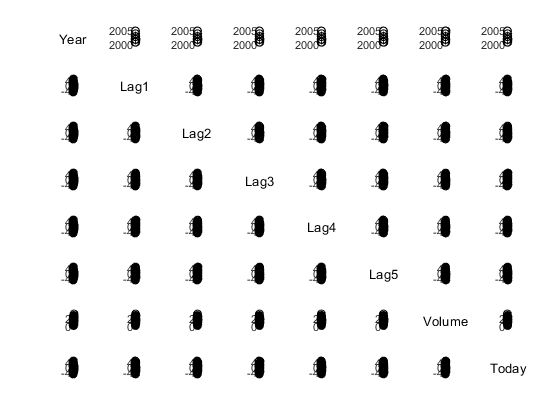

plotCorr(Smarket(:,1:end-1))

Show pairwise correlations among the predictors in a data set

array2table(corr(Smarket{:,1:end-1}),'VariableNames',Smarket.Properties.VariableNames(1:end-1),...
    'RowNames',Smarket.Properties.VariableNames(1:end-1))

ans = 8×8 table
                Year         Lag1          Lag2          Lag3          Lag4          Lag5        Volume        Today   
              ________    __________    __________    __________    __________    __________    _________    __________

    Year             1        0.0297      0.030596      0.033195      0.035689      0.029788      0.53901      0.030095
    Lag1        0.0297             1     -0.026294     -0.010803    -0.0029859    -0.0056746      0.04091     -0.026155
    Lag2      0.030596     -0.026294             1     -0.025897     -0.010854    -0.0035579    -0.043383      -0.01025
    Lag3      0.033195     -0.010803     -0

Plot the data we see that Volume is increasing over time

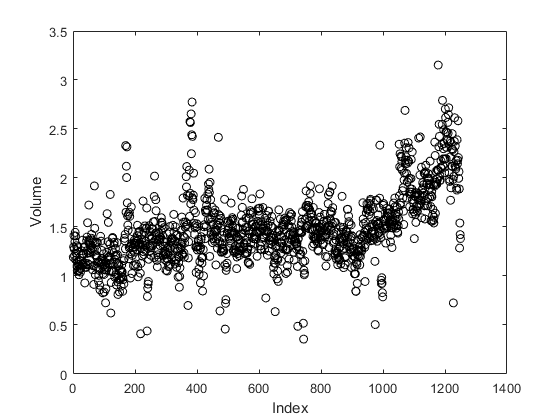

figure
plot(Smarket.Volume,'o','Color','k');
xlabel 'Index'
ylabel 'Volume'

### **4.6.2 Logistic Regression**

[Generalized linear model regression](https://www.mathworks.com/help/releases/R2019b/stats/glmfit.html)

[Create generalized linear regression model](https://www.mathworks.com/help/releases/R2019b/stats/fitglm.html)

Fit a logistic regression binomial model:

glmFit = fitglm(Smarket,'Direction ~ Lag1 + Lag2 + Lag3 + Lag4 + Lag5 + Volume',...
    'Distribution','binomial')

glmFit = Generalized linear regression model:
    logit(P(Direction='Up')) ~ 1 + Lag1 + Lag2 + Lag3 + Lag4 + Lag5 + Volume
    Distribution = Binomial

Estimated Coefficients:
                   Estimate        SE        tStat      pValue 
                   _________    ________    ________    _______

    (Intercept)       -0.126     0.24074    -0.52339     0.6007
    Lag1           -0.073074    0.050168     -1.4566    0.14523
    Lag2           -0.042301    0.050086    -0.84457    0.39835
    Lag3            0.011085    0.049939     0.22197    0.82433
    Lag4           0.0093589    0.049974     0.18727    0.85145
    Lag5            0.010313    0.049512      0.2083      0.835
    Volume           0.13544     0.15836     0.85527    

Coefficients for this fitted model

glmFit.Coefficients

ans = 7×4 table
                   Estimate        SE        tStat      pValue 
                   _________    ________    ________    _______

    (Intercept)       -0.126     0.24074    -0.52339     0.6007
    Lag1           -0.073074    0.050168     -1.4566    0.14523
    Lag2           -0.042301    0.050086    -0.84457    0.39835
    Lag3            0.011085    0.049939     0.22197    0.82433
    Lag4           0.0093589    0.049974     0.18727    0.85145
    Lag5            0.010313    0.049512      0.2083      0.835
    Volume           0.13544     0.15836     0.85527     0.3924


Show the p-values for the coefficients

glmFit.Coefficients(:,end)

ans = 7×1 table
                   pValue 
                   _______

    (Intercept)     0.6007
    Lag1           0.14523
    Lag2           0.39835
    Lag3           0.82433
    Lag4           0.85145
    Lag5             0.835
    Volume          0.3924


Predict the probability that the market will go up, given values of the predictors

glmProbs = glmFit.Fitted{:,'Response'};
glmProbs(1:10).'

ans =     0.5071    0.4815    0.4811    0.5152    0.5108    0.5070    0.4927    0.5092    0.5176    0.4888


Returns the coding that Matlab uses for the dummy variables

contrasts(Smarket.Direction)

ans = 2×1 table
            Up
            __

    Down    0 
    Up      1 


glmPred = repelem(categorical({'Down'}),1250);
glmPred(glmProbs > 0.5) = categorical({'Up'});

Produce a confusion matrix in order to determine how many observations were correctly or incorrectly classified

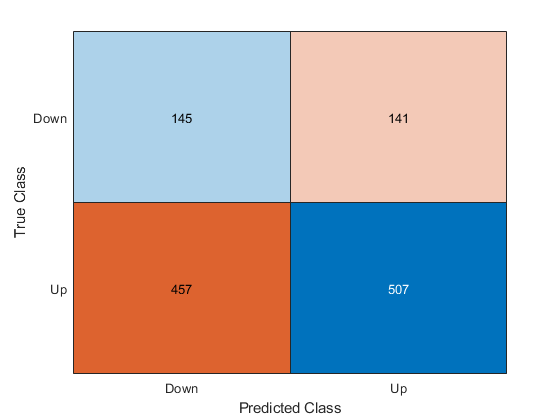

confusionchart(glmPred,Smarket.Direction);

% or
confusiontable(glmPred,Smarket.Direction)

ans = 2×2 table
                     . Down    . Up
                     ______    ____

    glmPred. Down     145      141 
    glmPred. Up       457      507 


(507 + 145)/1250

ans = 0.5216

The mean() function can be used to compute the fraction of days for which the prediction was correct

mean(glmPred' == Smarket.Direction)

ans = 0.5216

Create a vector corresponding to the observations from 2001 through 2004. We will then use this vector to create a held out data set of observations from 2005

train = (Smarket.Year < 2005);
Smarket2005 = Smarket(~train,:);
size(Smarket2005)

ans =    252     9


Direction2005 = Smarket.Direction(~train);

Fit a logistic regression model using only the subset of the observations that correspond to dates before 2005, using the subset train

glmFit = fitglm(Smarket(train,:),'Direction ~ Lag1 + Lag2 + Lag3 + Lag4 + Lag5 + Volume',...
    'Distribution','binomial')

glmFit = Generalized linear regression model:
    logit(P(Direction='Up')) ~ 1 + Lag1 + Lag2 + Lag3 + Lag4 + Lag5 + Volume
    Distribution = Binomial

Estimated Coefficients:
                    Estimate        SE         tStat      pValue 
                   __________    ________    _________    _______

    (Intercept)       0.19121     0.33369      0.57302    0.56663
    Lag1            -0.054178    0.051786      -1.0462    0.29547
    Lag2            -0.045805    0.051797     -0.88432    0.37652
    Lag3            0.0072001    0.051644      0.13942    0.88912
    Lag4            0.0064409    0.051706      0.12457    0.90087
    Lag5           -0.0042227    0.051138    -0.082573    0.93419
    Volume           -0.11626     0.2396

Obtain predicted probabilities of the stock market going up for each of the days in our test set- that is, for the days in 2005

glmProbs = predict(glmFit,Smarket2005);

Finally, we compute the predictions for 2005 and compare them to the actual movements of the market over that time period

glmPred = repelem(categorical({'Down'}),252);
glmPred(glmProbs > 0.5) = categorical({'Up'});
confusiontable(glmPred,Direction2005)

ans = 2×2 table
                     Direction2005. Down    Direction2005. Up
                     ___________________    _________________

    glmPred. Down            77                    97        
    glmPred. Up              34                    44        


mean(glmPred' == Direction2005)

ans = 0.4802

mean(glmPred' ~= Direction2005)

ans = 0.5198

Refit the logistic regression using just Lag1 and Lag2, which seemed to have the highest predictive power in the original logistic regression model

glmFit = fitglm(Smarket(train,{'Direction','Lag1','Lag2'}),'Direction ~ Lag1 + Lag2',...
    'Distribution','binomial');
glmProbs = predict(glmFit,Smarket2005);
glmPred = repelem(categorical({'Down'}),252);
glmPred(glmProbs > 0.5) = categorical({'Up'});
confusiontable(glmPred,Direction2005)

ans = 2×2 table
                     Direction2005. Down    Direction2005. Up
                     ___________________    _________________

    glmPred. Down            35                     35       
    glmPred. Up              76                    106       


mean(glmPred' == Direction2005)

ans = 0.5595

106/(106 + 76)

ans = 0.5824

Predict Direction on a day when Lag1 and Lag2 equal 1.2 and 1.1, respectively, and on a day when they equal 1.5 and −0.8

predict(glmFit,[1.2, 1.5;1.1, -0.8]')

ans =     0.4791
    0.4961


### 4.6.3 Linear Discriminant Analysis

ldaFit = fitcdiscr(Smarket(train,:),'Direction ~ Lag1 + Lag2')

ldaFit =   ClassificationDiscriminant
           PredictorNames: {'Lag1'  'Lag2'}
             ResponseName: 'Direction'
    CategoricalPredictors: []
               ClassNames: [Down    Up]
           ScoreTransform: 'none'
          NumObservations: 998
              DiscrimType: 'linear'
                       Mu: [2×2 double]
                   Coeffs: [2×2 struct]


  Properties, Methods


Groups

ldaFit.ClassNames % Groups

ans = 2×1 categorical array
     Down 
     Up 


Prior probabilities of groups: 

% ldaFit.Prior % Prior probabilities of groups : 
array2table(ldaFit.Prior,'VariableNames',cellstr(ldaFit.ClassNames))

ans = 1×2 table
     Down        Up   
    _______    _______

    0.49198    0.50802


Group means

% ldaFit.Mu % Group means
array2table(ldaFit.Mu,'VariableNames',ldaFit.PredictorNames,...
    'RowNames',cellstr(ldaFit.ClassNames))

ans = 2×2 table
              Lag1         Lag2   
            _________    _________

    Down      0.04279     0.033894
    Up      -0.039546    -0.031325


Predict labels using discriminant analysis classification model

[ldaPredClass,ldaPredPosterior] = predict(ldaFit,Smarket2005);
confusiontable(ldaPredClass,Direction2005)

ans = 2×2 table
                          Direction2005. Down    Direction2005. Up
                          ___________________    _________________

    ldaPredClass. Down            35                     35       
    ldaPredClass. Up              76                    106       


mean(ldaPredClass == Direction2005)

ans = 0.5595

Applying a 50 % threshold to the posterior probabilities allows us to recreate the predictions contained

sum(ldaPredPosterior(:,1) >= 0.5)

ans = 70

sum(ldaPredPosterior(:,1) < 0.5)

ans = 182

ldaPredPosterior(1:20,1).'

ans =     0.4902    0.4792    0.4668    0.4740    0.4928    0.4939    0.4951    0.4873    0.4907    0.4844    0.4907    0.5120    0.4895    0.4707    0.4745    0.4800    0.4936    0.5031    0.4979    0.4886


ldaPredClass(1:20,1).'

ans = 1×20 categorical array
     Up      Up      Up      Up      Up      Up      Up      Up      Up      Up      Up      Down      Up      Up      Up      Up      Up      Down      Up      Up 


Suppose that we wish to predict a market decrease only if we are very certain that the market will indeed decrease on that day—say, if the posterior probability is at least 90 %

sum(ldaPredPosterior(:,1) >= 0.9)

ans = 0

### 4.6.4 Quadratic Discriminant Analysis

lqaFit = fitcdiscr(Smarket(train,:),'Direction ~ Lag1 + Lag2',...
    'DiscrimType','quadratic')

lqaFit =   ClassificationDiscriminant
           PredictorNames: {'Lag1'  'Lag2'}
             ResponseName: 'Direction'
    CategoricalPredictors: []
               ClassNames: [Down    Up]
           ScoreTransform: 'none'
          NumObservations: 998
              DiscrimType: 'quadratic'
                       Mu: [2×2 double]
                   Coeffs: [2×2 struct]


  Properties, Methods


Groups

lqaFit.ClassNames

ans = 2×1 categorical array
     Down 
     Up 


Prior probabilities of groups: 

array2table(lqaFit.Prior,'VariableNames',cellstr(lqaFit.ClassNames))

ans = 1×2 table
     Down        Up   
    _______    _______

    0.49198    0.50802


Group means

array2table(lqaFit.Mu,'VariableNames',lqaFit.PredictorNames,...
    'RowNames',cellstr(lqaFit.ClassNames))

ans = 2×2 table
              Lag1         Lag2   
            _________    _________

    Down      0.04279     0.033894
    Up      -0.039546    -0.031325


lqaPredClass = predict(lqaFit,Smarket2005);
confusiontable(lqaPredClass,Direction2005)

ans = 2×2 table
                          Direction2005. Down    Direction2005. Up
                          ___________________    _________________

    lqaPredClass. Down            30                     20       
    lqaPredClass. Up              81                    121       


mean(lqaPredClass == Direction2005)

ans = 0.5992

### 4.6.5 K-Nearest Neighbors

Fit *k*-nearest neighbor classifier

rng default;
knnFit = fitcknn(Smarket(train,:),'Direction ~ Lag1 + Lag2','NumNeighbors',1)

knnFit =   ClassificationKNN
           PredictorNames: {'Lag1'  'Lag2'}
             ResponseName: 'Direction'
    CategoricalPredictors: []
               ClassNames: [Down    Up]
           ScoreTransform: 'none'
          NumObservations: 998
                 Distance: 'euclidean'
             NumNeighbors: 1


  Properties, Methods


knnPred = predict(knnFit,Smarket2005);
confusiontable(knnPred,Direction2005)

ans = 2×2 table
                     Direction2005. Down    Direction2005. Up
                     ___________________    _________________

    knnPred. Down            43                    58        
    knnPred. Up              68                    83        


mean(knnPred == Direction2005)

ans = 0.5000

rng default;
knnFit = fitcknn(Smarket(train,:),'Direction ~ Lag1 + Lag2','NumNeighbors',3)

knnFit =   ClassificationKNN
           PredictorNames: {'Lag1'  'Lag2'}
             ResponseName: 'Direction'
    CategoricalPredictors: []
               ClassNames: [Down    Up]
           ScoreTransform: 'none'
          NumObservations: 998
                 Distance: 'euclidean'
             NumNeighbors: 3


  Properties, Methods


knnPred = predict(knnFit,Smarket2005);
confusiontable(knnPred,Direction2005)

ans = 2×2 table
                     Direction2005. Down    Direction2005. Up
                     ___________________    _________________

    knnPred. Down            48                    55        
    knnPred. Up              63                    86        


### 4.6.6 An Application to Caravan Insurance Data

clear all; clc; close all;
Caravan = readtable("Data\Caravan.csv", 'TreatAsEmpty',{'?','NA','N/A'},'ReadRowNames', true);
Caravan.Purchase = categorical(Caravan.Purchase);
size(Caravan)

ans =         5822          86


summary(Caravan.Purchase)

     No       5474 
     Yes       348 


348/5822

ans = 0.0598

Standardize the data so that all variables (exclude column 86 Purchase) are given a mean of zero and a standard deviation of one

standardizedX = zscore(Caravan{:,1:end-1});
var(Caravan{:,1})

ans = 165.0378

var(Caravan{:,2})

ans = 0.1647

var(standardizedX(:,1))

ans = 1.0000

var(standardizedX(:,2))

ans = 1.0000

test = [repelem(true,1000), repelem(false,size(standardizedX,1) - 1000)];

Method 1:

rng default;
knnFit = fitcknn(standardizedX(~test,:),Caravan.Purchase(~test),'NumNeighbors',1);
knnPred = predict(knnFit,standardizedX(test,:));
mean(knnPred ~= Caravan.Purchase(test))

ans = 0.1180

mean(Caravan.Purchase(test) ~= categorical({'No'}))

ans = 0.0590

Method 2:

rng default;
knnFit2 = fitcknn(Caravan(~test,:),'Purchase',"Standardize",true,'NumNeighbors',1);
knnPred2 = predict(knnFit,Caravan{test,1:end-1});
confusiontable(knnPred2,Caravan.Purchase(test))

ans = 2×2 table
                     . No    . Yes
                     ____    _____

    knnPred2. No     893      50  
    knnPred2. Yes     48       9  


mean(knnPred2 ~= Caravan.Purchase(test))

ans = 0.0980

confusiontable(knnPred,Caravan.Purchase(test))

ans = 2×2 table
                    . No    . Yes
                    ____    _____

    knnPred. No     873      50  
    knnPred. Yes     68       9  


9/(68 + 9)

ans = 0.1169

rng default;
knnFit = fitcknn(standardizedX(~test,:),Caravan.Purchase(~test),'NumNeighbors',3);
knnPred = predict(knnFit,standardizedX(test,:));
confusiontable(knnPred,Caravan.Purchase(test))

ans = 2×2 table
                    . No    . Yes
                    ____    _____

    knnPred. No     921      54  
    knnPred. Yes     20       5  


5/(5 + 20)

ans = 0.2000


rng default;
knnFit = fitcknn(standardizedX(~test,:),Caravan.Purchase(~test),'NumNeighbors',5);
knnPred = predict(knnFit,standardizedX(test,:));
confusiontable(knnPred,Caravan.Purchase(test))

ans = 2×2 table
                    . No    . Yes
                    ____    _____

    knnPred. No     930      55  
    knnPred. Yes     11       4  


4/(4 + 11)

ans = 0.2667

As a comparison, we can also fit a logistic regression model to the data

glmFit = fitglm(Caravan(~test,:),'ResponseVar','Purchase','Distribution','binomial');

glmProbs = predict(glmFit,Caravan(test,:));
glmPred = repelem(categorical({'No'}),1000);
glmPred(glmProbs > 0.5) = categorical({'Yes'});
confusiontable(glmPred,Caravan.Purchase(test))

ans = 2×2 table
                    . No    . Yes
                    ____    _____

    glmPred. No     934      59  
    glmPred. Yes      7       0  


0/(0 + 7)

ans = 0


glmPred(glmProbs > 0.25) = categorical({'Yes'});
confusiontable(glmPred,Caravan.Purchase(test))

ans = 2×2 table
                    . No    . Yes
                    ____    _____

    glmPred. No     919      48  
    glmPred. Yes     22      11  


11/(22 + 11)

ans = 0.3333

[Local functions](https://www.mathworks.com/help/matlab/ref/localfunctions.html), used in the main program

function plotCorr(Table)
%  Plot variable correlations like corrplot function
    figure
    names = Table.Properties.VariableNames;
    tiledlayout(length(names),length(names)); % Requires R2019b or later
    for i = 1:length(names)
        for j = 1:length(names)
            nexttile
            if i == j
                set(gca,'visible','off','xlim',[0 2],'ylim',[0 2],'Position',[0 0 1 1]) ;
                set(text(1,1,names(i)),'visible','on',...
                    'HorizontalAlignment','center','VerticalAlignment','middle');
            else
                plot(Table{:,j},Table{:,i},'o','Color','k');
            end
        end
    end
end
function contrasts(var)
% Set and view the contrasts associated with a factor like function
% contrasts in R
    namesCategorical = cellstr(unique(var));
    array2table([zeros(1,length(namesCategorical)-1); eye(length(namesCategorical)-1)],...
        'VariableNames',namesCategorical(2:end),...
        'RowNames',namesCategorical)
end